# **Denoising a signal using FIR and IIR filters**

% Read in the file
load('DSPLab_EndSem2021_DataFileFor_190020039.mat');
% playing original signal x
sound(x,44100);

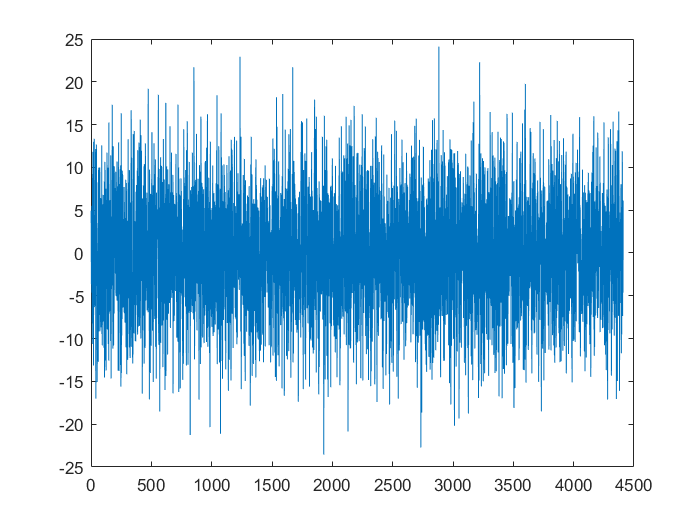

% visualising a part of the signal x
plot(x(1:4410))

N = length(x);
% DFT of signal x
X = fft(x,N);

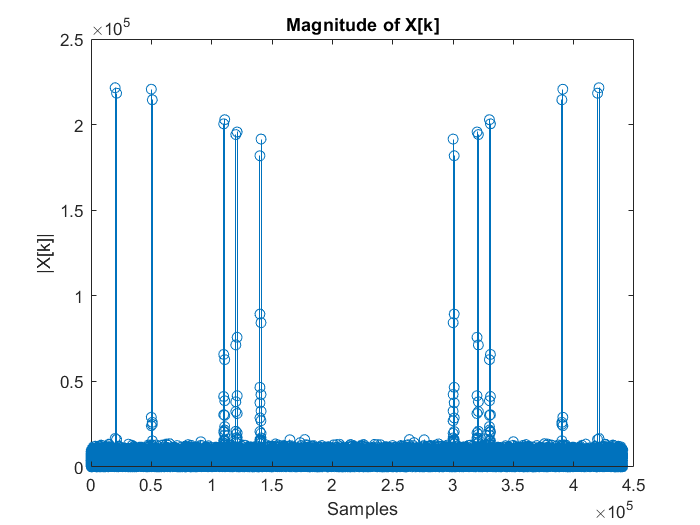

% Plot Magnitude of X
stem(0:N-1,abs(X));
xlabel('Samples')
ylabel('|X[k]|')
title('Magnitude of X[k]')

## FIR implementation

% Designing the high pass filter
Fs = 44100;  % Sampling Frequency
Fstop = 5000;     % Stopband Frequency
Fpass = 11000;    % Passband Frequency
Dstop = 0.01;     % Stopband Attenuation
Dpass = 0.01;     % Passband Ripple
flag  = 'scale';  % Sampling Flag
% Calculate the order from the parameters using KAISERORD.
[N1,Wn,BETA,TYPE] = kaiserord([Fstop Fpass]/(Fs/2), [0 1], [Dpass Dstop]);
% Calculate the coefficients using the FIR1 function.
b  = fir1(N1, Wn, TYPE, kaiser(N1+1, BETA), flag);

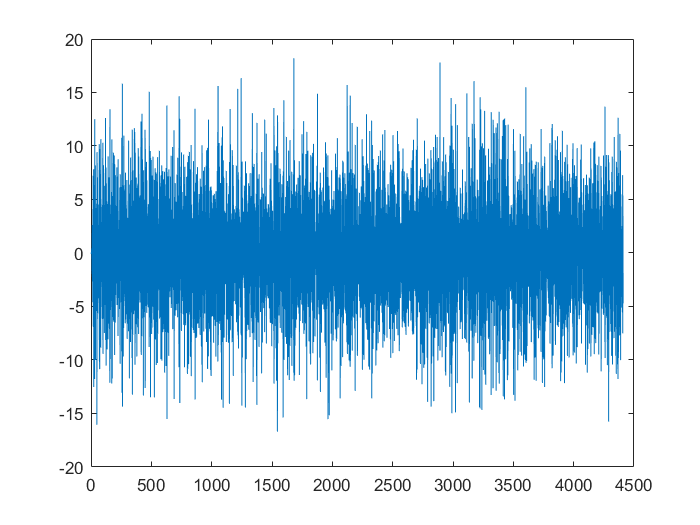

% filtering signal x
x_filtered = filter(b,1,x);
% plotting filtered signal x_filtered
plot(x_filtered(1:4410))

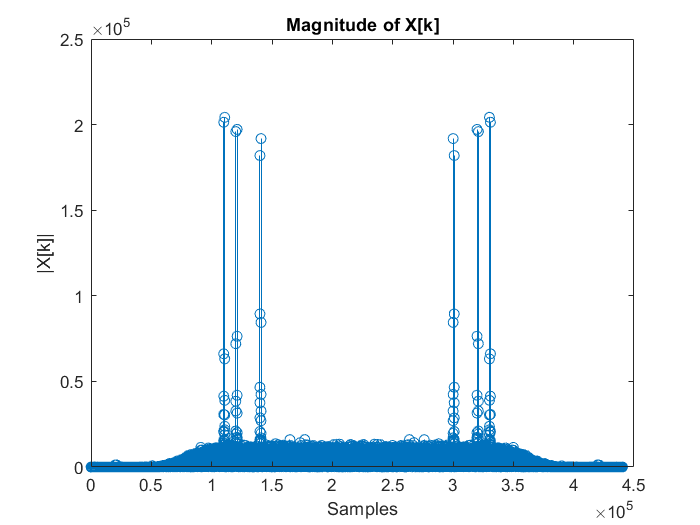

% DFT of x_filtered
X_filtered = fft(x_filtered,N);
% Plot Magnitude of X_filtered
stem(0:N-1,abs(X_filtered));
xlabel('Samples')
ylabel('|X[k]|')
title('Magnitude of X[k]')

% playing filtered signal x_filtered
sound(x_filtered, 44100);

% removing noise from signal
X_denoised = X_filtered;
for i=1:length(X_filtered)
    if abs(X_filtered(i)) < (16000)
        X_denoised(i)=0;
    end
end

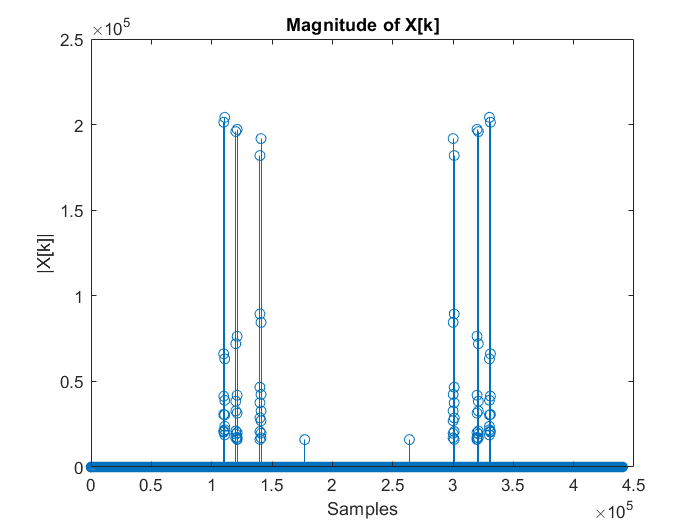

% Plot Magnitude of X_denoised
stem(0:N-1,abs(X_denoised));
xlabel('Samples')
ylabel('|X[k]|')
title('Magnitude of X[k]')

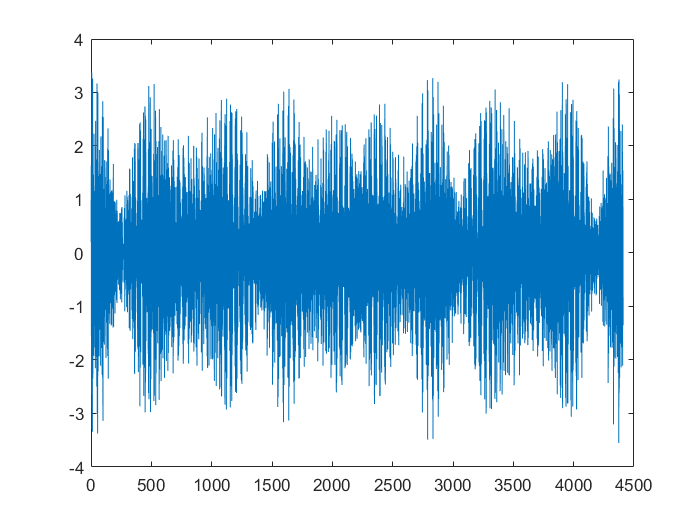

% IDFT of X_denoised
x_denoised = ifft(X_denoised);
% visualising denoised signal x_denoised
plot(x_denoised(1:4410))

% playing denoised signal x_denoised
sound(x_denoised,44100);

## IIR implementation

Fstop = 5000;   % Stopband Frequency
Fpass = 11000;  % Passband Frequency
Astop = 80;     % Stopband Attenuation (dB)
Apass = 1;      % Passband Ripple (dB)
Fs    = 44100;  % Sampling Frequency

h = fdesign.highpass('fst,fp,ast,ap', Fstop, Fpass, Astop, Apass, Fs);

Hd = design(h, 'cheby2','MatchExactly', 'stopband','SystemObject', true);

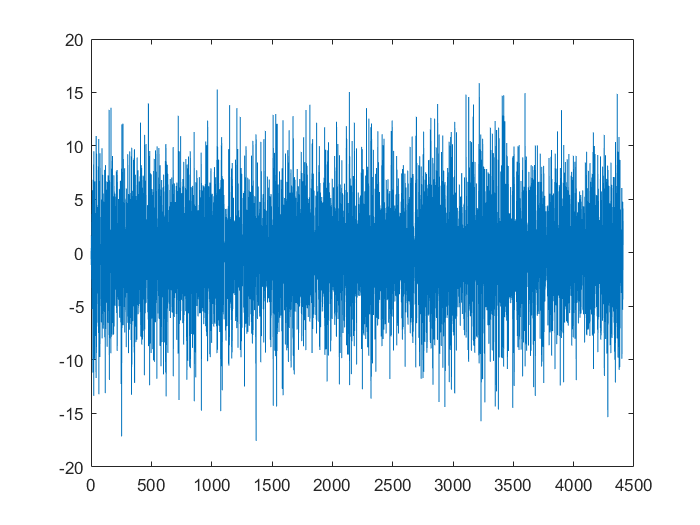

% filtering signal x
x_filtered = step(Hd,double(x));
% plotting filtered signal x_filtered
plot(x_filtered(1:4410))

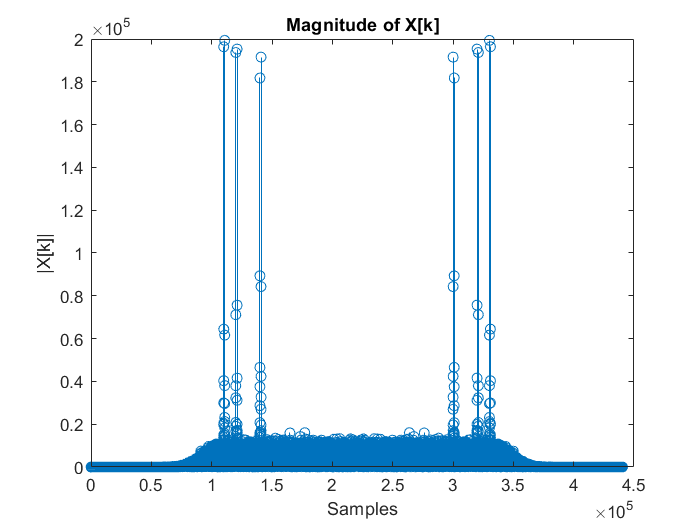

% DFT of x_filtered
X_filtered = fft(x_filtered,N);
% Plot Magnitude of X_filtered
stem(0:N-1,abs(X_filtered));
xlabel('Samples')
ylabel('|X[k]|')
title('Magnitude of X[k]')

% playing filtered signal x_filtered
sound(x_filtered, 44100);

% removing noise from signal
X_denoised = X_filtered;
for i=1:length(X_filtered)
    if abs(X_filtered(i)) < (17000)
        X_denoised(i)=0;
    end
end

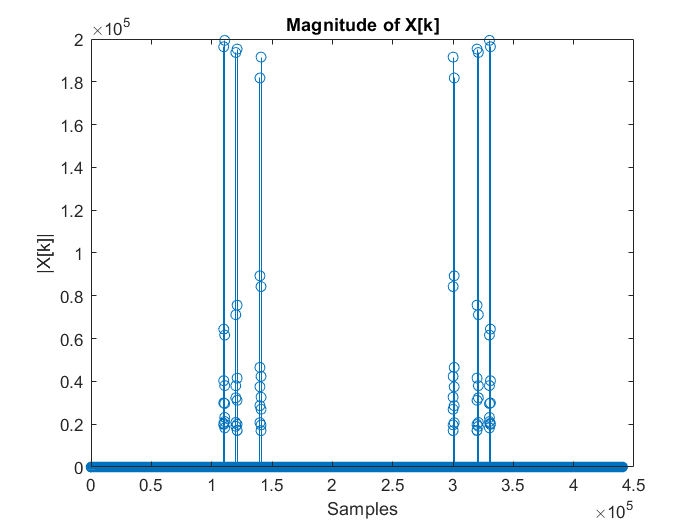

% Plot Magnitude of X_denoised
stem(0:N-1,abs(X_denoised));
xlabel('Samples')
ylabel('|X[k]|')
title('Magnitude of X[k]')

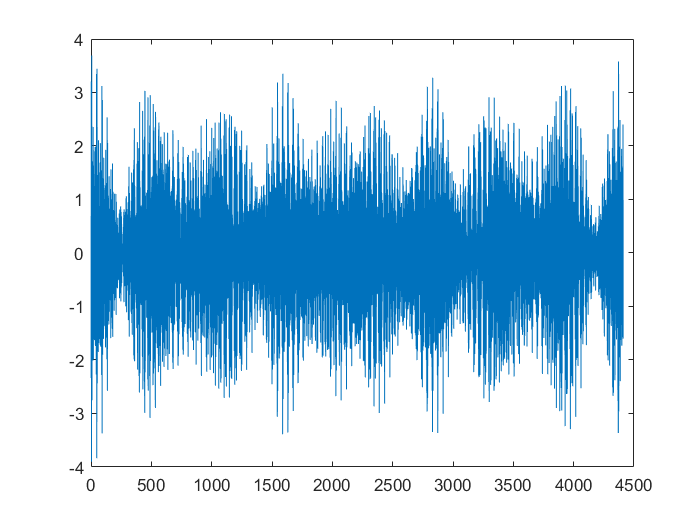

% IDFT of X_denoised
x_denoised = ifft(X_denoised);
% visualising denoised signal x_denoised
plot(x_denoised(1:4410))

% playing denoised signal x_denoised
sound(x_denoised,44100);

## Quantization to 4 bits:

max(abs(b))

ans = 0.6397

bq = round(b*2^3)/2^3;

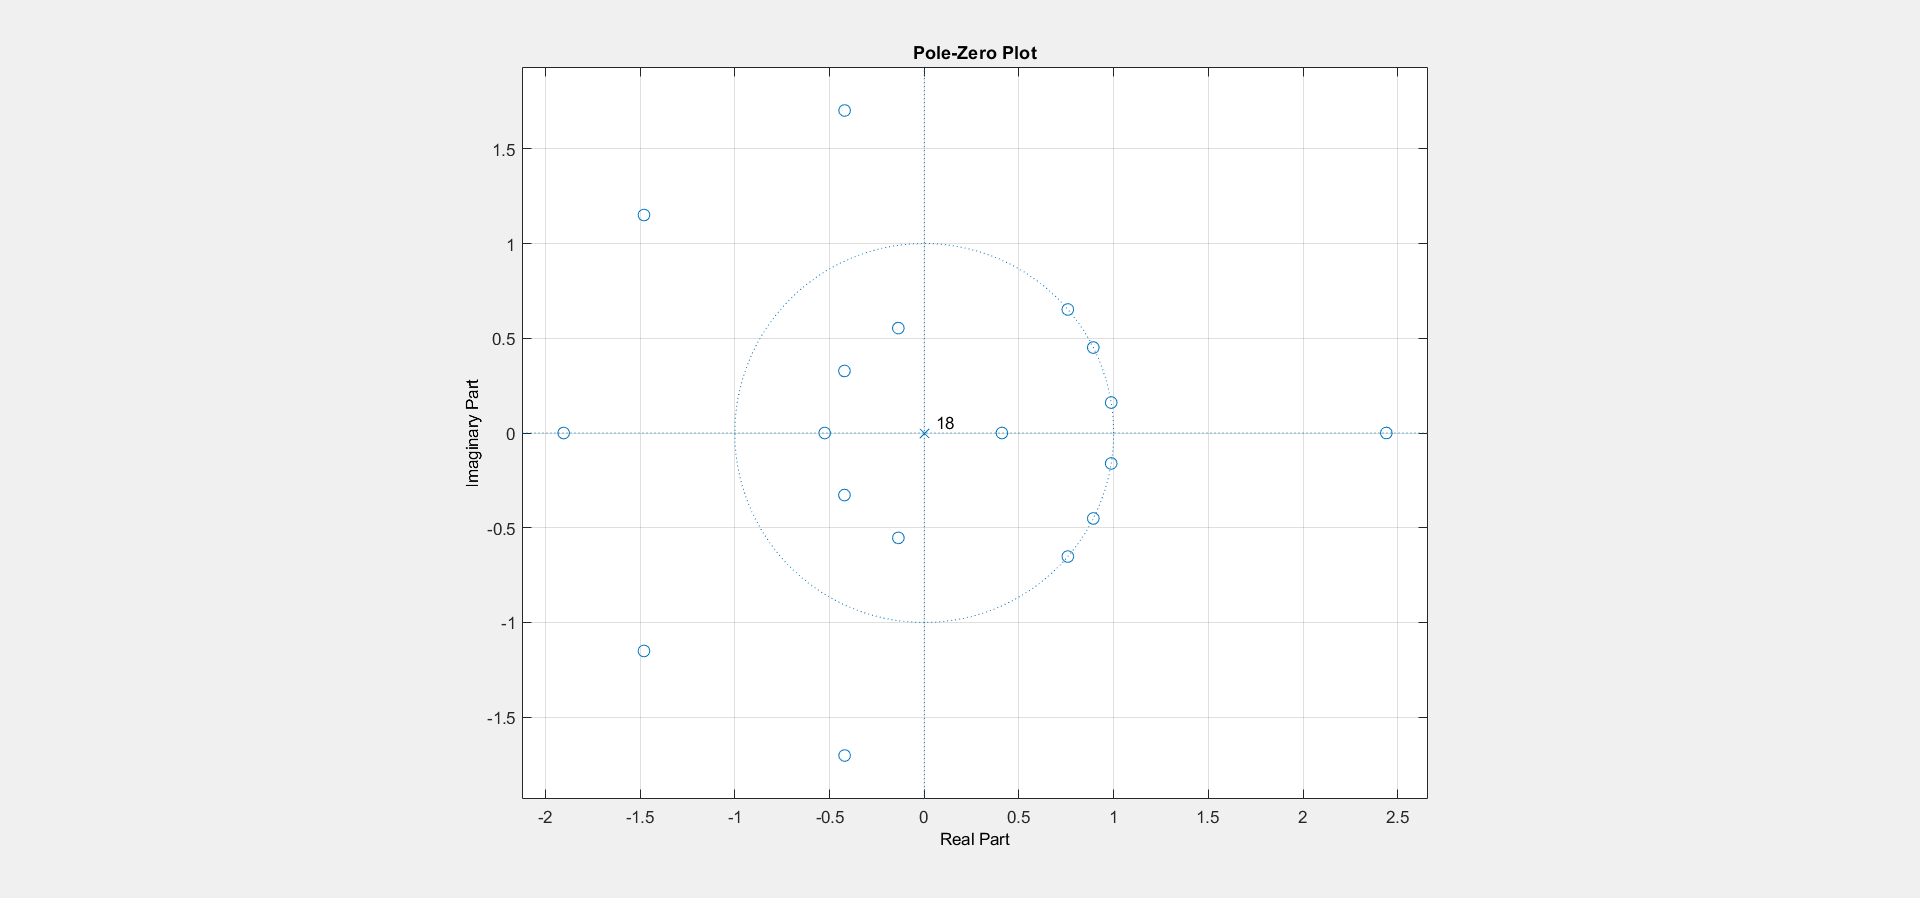

fvtool(b,'polezero')

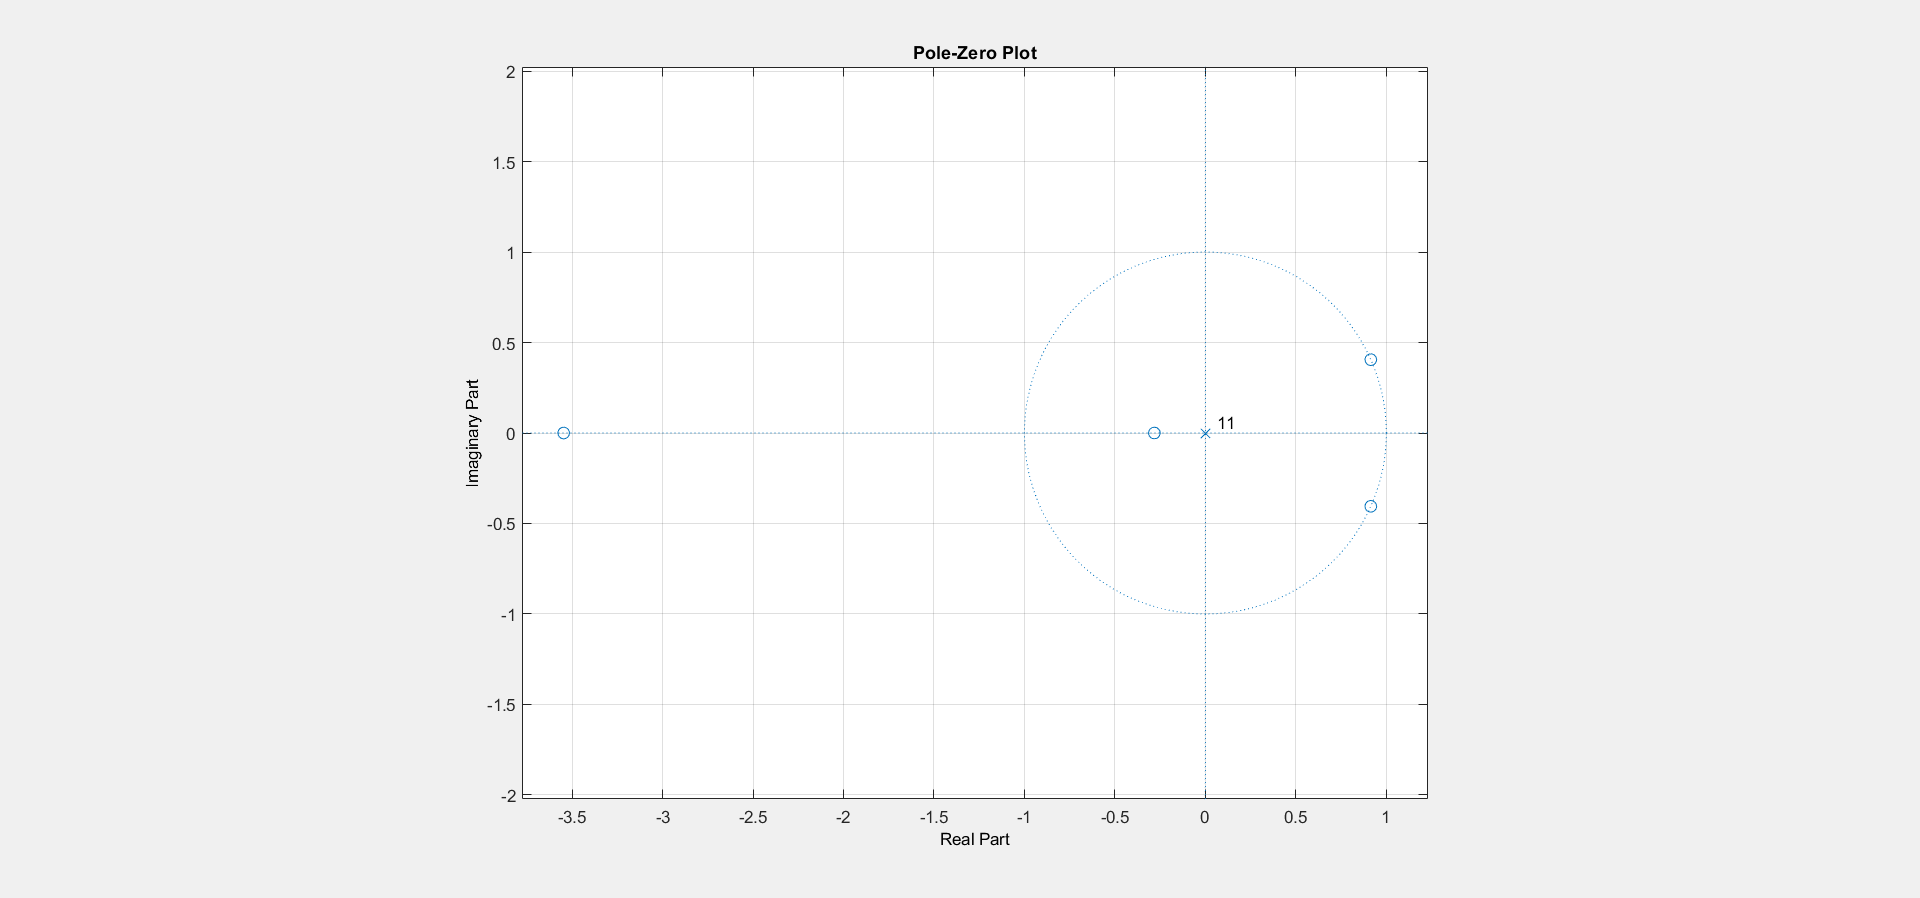

fvtool(bq,'polezero')

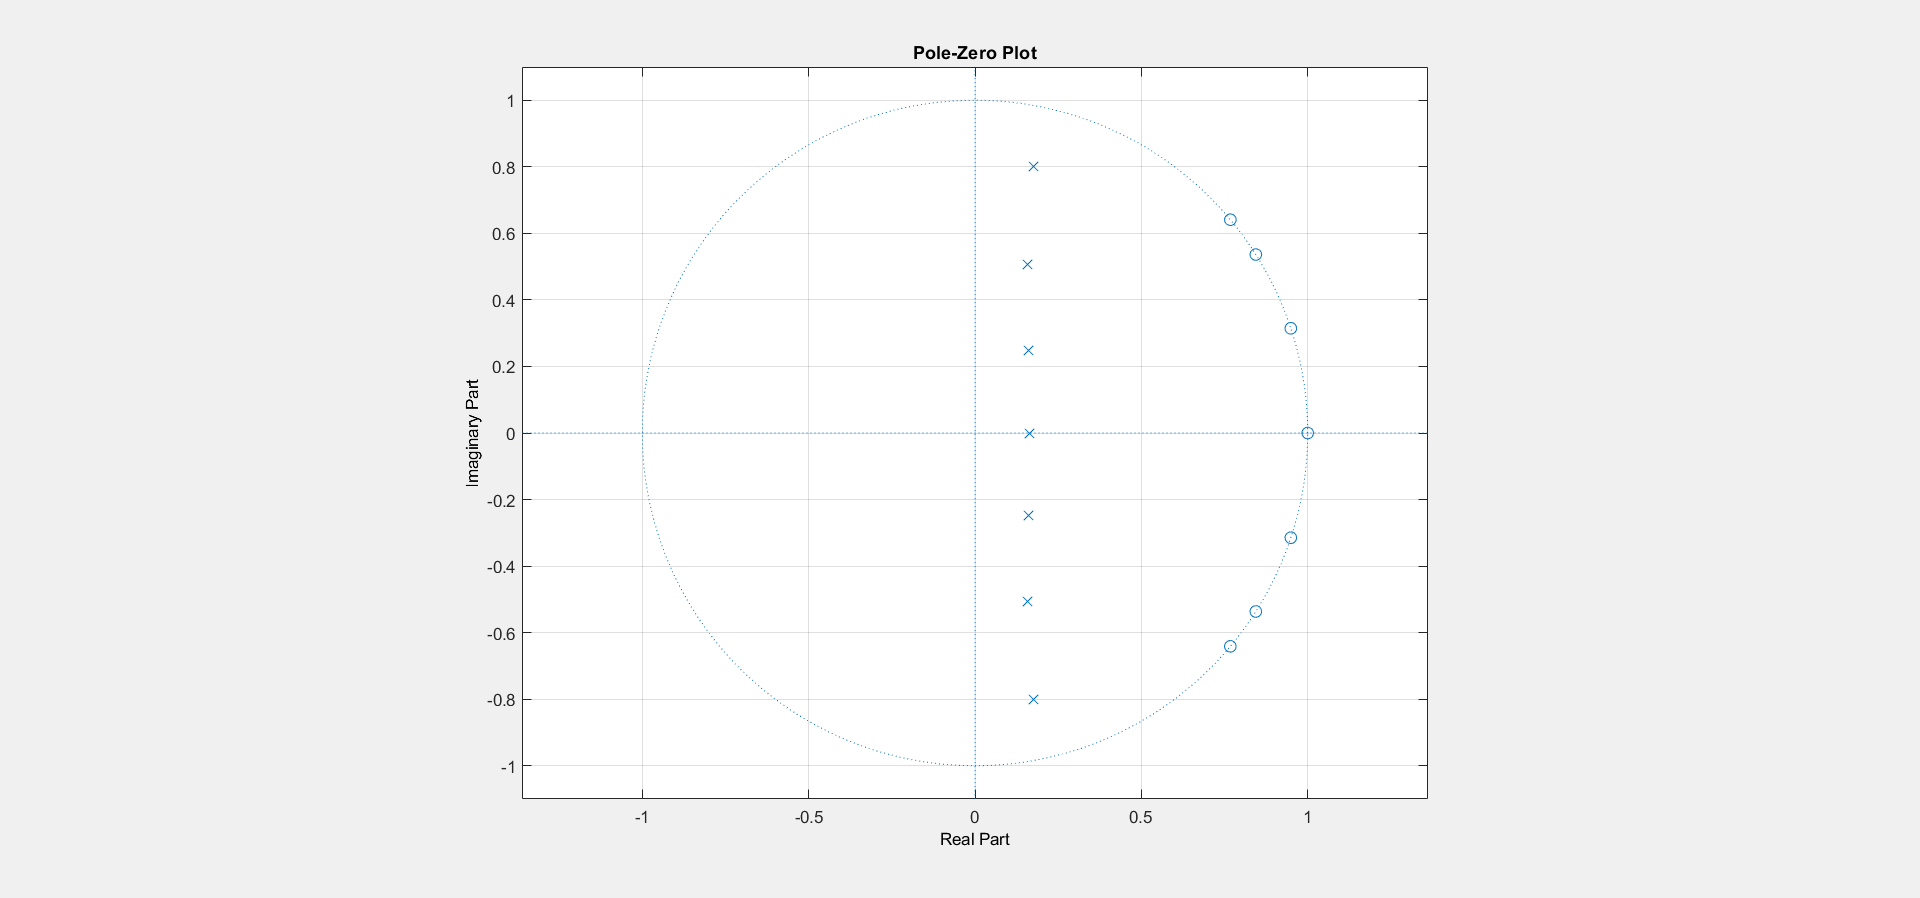

fvtool(Hd,'polezero')

sos = Hd.SOSMatrix

sos =     1.0000   -1.5349    1.0000    1.0000   -0.3545    0.6747
    1.0000   -1.6879    1.0000    1.0000   -0.3169    0.2819
    1.0000   -1.8984    1.0000    1.0000   -0.3200    0.0868
    1.0000   -1.0000         0    1.0000   -0.1625         0


max(max(abs(sos)))

ans = 1.8984

sosq = round(sos*2^2)/2^2

sosq =     1.0000   -1.5000    1.0000    1.0000   -0.2500    0.7500
    1.0000   -1.7500    1.0000    1.0000   -0.2500    0.2500
    1.0000   -2.0000    1.0000    1.0000   -0.2500         0
    1.0000   -1.0000         0    1.0000   -0.2500         0


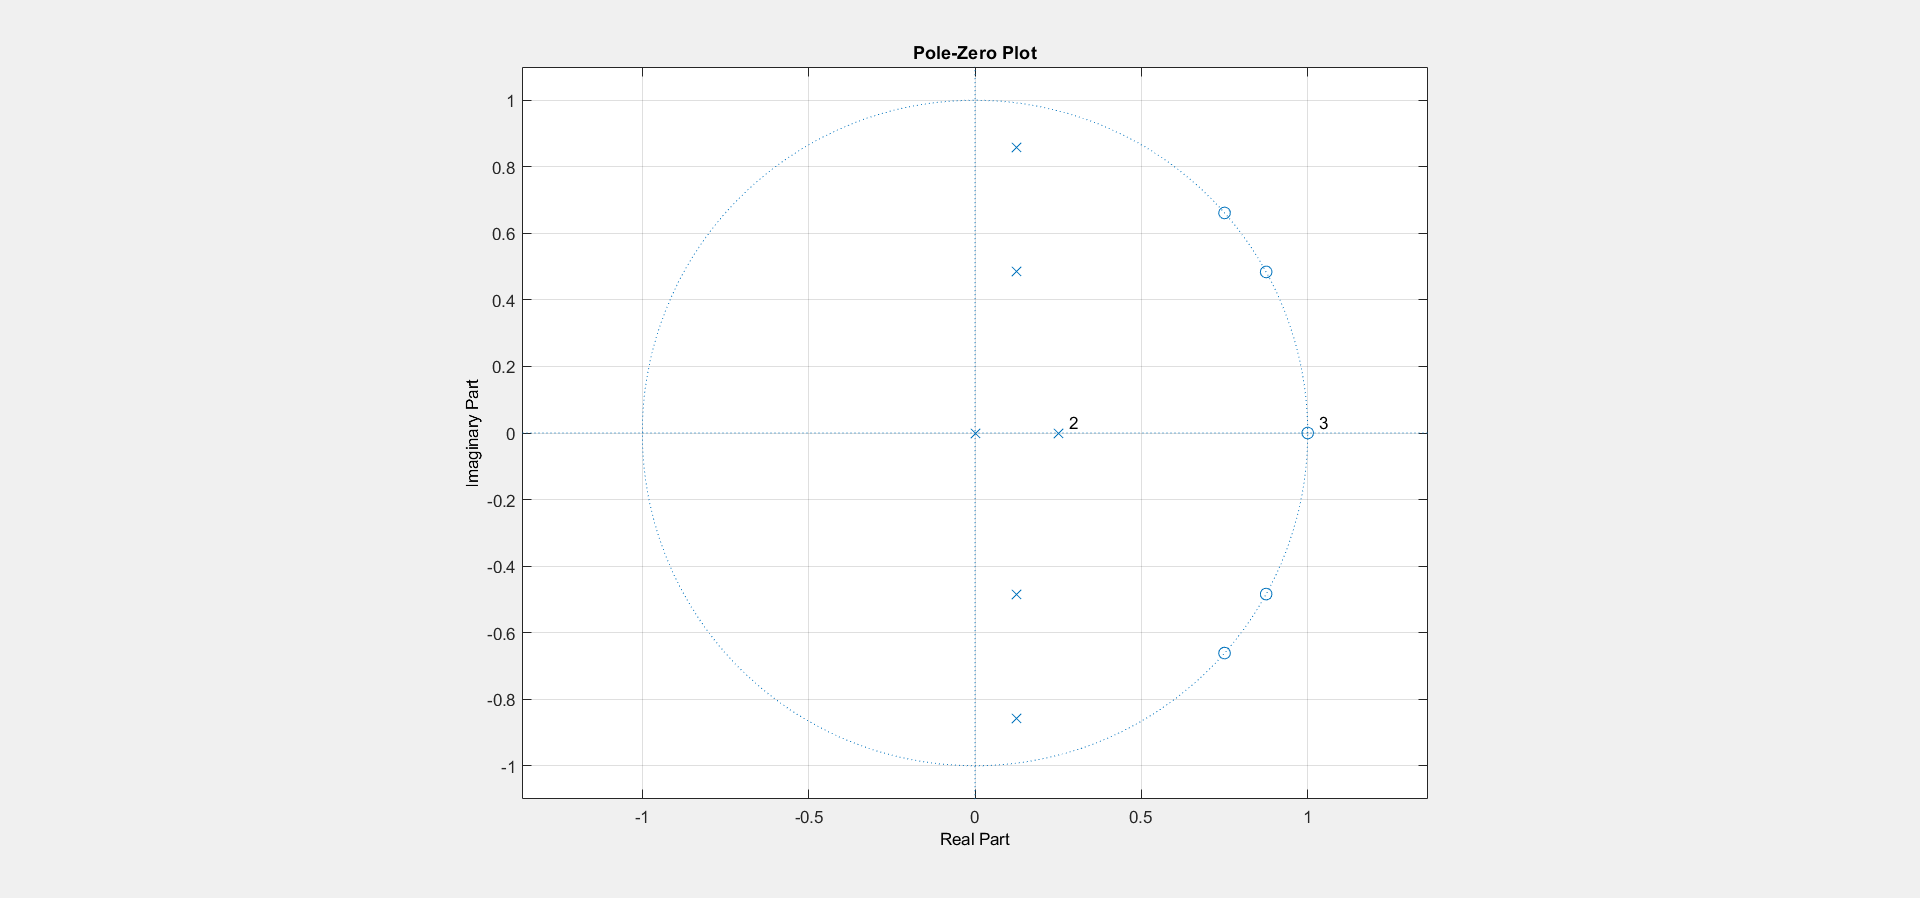

fvtool(sosq,'polezero')